# 9주차 과제 — 주파수응답과 보드 선도

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — $s$ 에 $j\omega$ 를 넣어 손으로 계산

- **2. 기본** (중간 · 40분 · 70점) — 점근선으로 손작도하고 `bode` 와 대조

- **3. 도전** (선택 · 가산점 10점) — Simulink 로 직접 측정

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 손으로 $G(j\omega)$ 구하기

**강의노트 0-1절을 그대로 보면 됩니다.**

주파수응답은 어려운 계산이 아닙니다. $s$ 자리에 $j\omega$ 를 넣고 복소수의 크기와 각을 구하면 끝입니다.


$$G(s) = \frac{1}{s+2}$$



$$G(j\omega) = \frac{1}{j\omega + 2} \quad\Rightarrow\quad |G| = \frac{1}{\sqrt{\omega^2 + 4}}, \qquad \angle G = -\arctan\frac{\omega}{2}$$


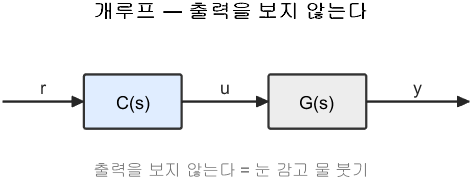

측정 대상은 열린 시스템이다

**그림 파일** `loop_open.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_open')`

## 1-1. 손으로 채우기

아래 세 주파수에서 크기와 위상을 **손으로** 구하십시오. 계산기만 있으면 됩니다.

- $\omega = 0$

- $\omega = 2$

- $\omega = 20$

그다음 `TODO` 두 줄을 채워 확인하십시오.

G = 1/(s+2);
ws = [0 2 20];

fprintf('     w      크기     크기[dB]   위상[도]\n');
fprintf('   -----  --------  ---------  ---------\n');
for w = ws
    Gjw = NaN;    % TODO : freqresp(G, w) 를 쓰십시오
    if isnan(Gjw)
        fprintf('   %5.1f  (아직 안 채움)\n', w);
        continue
    end
    m = NaN;      % TODO : abs(Gjw) 로 크기를 구하십시오
    if isnan(m)
        fprintf('   %5.1f  (크기 TODO 남음)\n', w);
        continue
    end
    fprintf('   %5.1f  %8.4f  %9.2f  %9.2f\n', ...
            w, m, 20*log10(m), rad2deg(angle(Gjw)));
end

## 1-2. 답할 것 (두 문장이면 됩니다)

- $\omega = 2$ 는 이 시스템의 **꺾임주파수**입니다. 그 자리의 크기가 저주파 값의 몇 배입니까? dB 로는 몇입니까?

- $\omega$ 를 아주 크게 하면 위상은 몇 도로 갑니까? 왜 그렇습니까?

**스스로 확인하는 법** — 꺾임주파수의 크기가 저주파의 $1/\sqrt{2}$ 배 (즉 $-3$ dB) 이면 맞은 것입니다.

## 2. 기본 — 점근선으로 손작도하기

**강의노트 5절과 5-2절을 그대로 보면 됩니다.**

강의노트에서 다룬 것과 **구조가 같고 숫자만 다른** 개루프입니다.


$$L(s) = \frac{20}{s\,(s+2)\,(0.05\,s + 1)}$$


순서대로 하나씩 밟습니다.

L = 20/(s*(s+2)*(0.05*s+1));

## 2-1. 1단계 : 시정수 꼴로 정리

$(s+2)$ 는 시정수 꼴이 아닙니다. 먼저 정리하십시오.


$$s + 2 = 2\,(0.5\,s + 1)$$


그러면 상수 조각이 얼마가 됩니까? 손으로 적어 보십시오.


$$L(s) = \frac{K_0}{s} \cdot \frac{1}{0.5s+1} \cdot \frac{1}{0.05s+1}, \qquad K_0 = \;?$$


K0 = NaN;      % TODO : 20/2 를 계산해 넣으십시오

fprintf('\n=== 2-1단계 : 시정수 꼴 ===\n');
if isnan(K0)
    fprintf('  K0 를 아직 안 채웠습니다.\n');
else
    fprintf('  K0 = %.2f  ( = %.2f dB )\n', K0, 20*log10(K0));
    fprintf('  꺾임주파수 : %.1f 과 %.1f rad s^-1\n', 1/0.5, 1/0.05);
end

## 2-2. 2단계 : 점근선 그리기

코드는 다 되어 있습니다. `K0` 만 채우면 그려집니다.

점근선은 세 조각의 합입니다.

- 상수와 적분기 : $20\log_{10}K_0 - 20\log_{10}\omega$

- 극점 $\omega = 2$ : $\omega > 2$ 부터 $-20$ dB per dec

- 극점 $\omega = 20$ : $\omega > 20$ 부터 $-20$ dB per dec

w = logspace(-1, 3, 600);
if ~isnan(K0)
    a_sum = 20*log10(K0) - 20*log10(w) ...
            - 20*log10(max(w/2, 1)) - 20*log10(max(w/20, 1));
    m_real = 20*log10(squeeze(abs(freqresp(L, w))));

    figure;
    semilogx(w, a_sum, '--', 'LineWidth', 2.5); hold on; grid on;
    semilogx(w, m_real, 'LineWidth', 2);
    xline(2, ':'); xline(20, ':');
    yline(0, 'k-');
    xlabel('주파수 [rad s^{-1}]'); ylabel('크기 [dB]');
    legend('내가 그린 점근선', '실제 bode 곡선', 'Location','southwest');
    title('점근선과 실제가 겹치는가');
end

## 2-3. 3단계 : 0 dB 를 지나는 주파수를 손으로 구하기

저주파에서는 적분기 조각만 보면 됩니다.


$$20\log_{10}\frac{K_0}{\omega} = 0 \quad\Rightarrow\quad \omega = K_0$$


**단, 이 식은 꺾임주파수보다 낮은 곳에서만 맞습니다.** $K_0$ 가 첫 꺾임주파수($\omega = 2$)보다 크면 다시 계산해야 합니다.

손으로 구한 값을 아래에 적고, `margin` 이 알려 주는 값과 비교하십시오.

wc_hand = NaN;    % TODO : 위 식으로 구한 값을 적으십시오

[~, ~, ~, wc_true] = margin(L);
fprintf('\n=== 2-3단계 : 교차주파수 ===\n');
if isnan(wc_hand)
    fprintf('  손계산 값을 아직 안 적었습니다.\n');
else
    fprintf('  손으로 구한 값 : %.3f rad s^-1\n', wc_hand);
end
fprintf('  margin 이 준 값 : %.3f rad s^-1\n', wc_true);
fprintf('  --> 차이가 크다면 꺾임주파수를 넘어섰다는 뜻입니다. 3-1절을 다시 보십시오.\n');

## 2-4. 4단계 : 사인을 넣어 한 점만 확인

점근선이 맞는지 **실제로 사인을 넣어** 확인해 봅니다. 코드는 다 되어 있습니다. 주파수 하나만 골라 넣으십시오.

w_check = 1;              % TODO : 원하는 주파수로 바꿔 보십시오 (예: 0.5, 1, 5)

Tp = 2*pi/w_check;
t  = (0:Tp/400:40*Tp)';
u  = sin(w_check*t);
y  = lsim(L, u, t);
keep = t > t(end) - 6*Tp;
Fu = trapz(t(keep), u(keep).*exp(-1j*w_check*t(keep)));
Fy = trapz(t(keep), y(keep).*exp(-1j*w_check*t(keep)));

fprintf('\n=== 2-4단계 : 사인을 넣어 확인 ===\n');
fprintf('  w = %.2f 에서\n', w_check);
fprintf('    사인으로 잰 크기 : %8.4f  ( %6.2f dB )\n', abs(Fy/Fu), 20*log10(abs(Fy/Fu)));
fprintf('    이론값 |L(jw)|   : %8.4f  ( %6.2f dB )\n', ...
        abs(freqresp(L,w_check)), 20*log10(abs(freqresp(L,w_check))));

## 2-5. 답할 것 (세 문장이면 됩니다)

- 점근선과 실제 곡선이 가장 크게 어긋나는 곳은 어디입니까? 몇 dB 입니까?

- 저주파에서 기울기가 $-20$ dB per dec 인 이유는 무엇입니까?

- $\omega = 100$ 근처에서 기울기는 몇 dB per dec 입니까? 왜 그렇습니까?

## 3. 도전 (선택) — Simulink 로 직접 측정

**강의노트 8절과 W09_03_run_simulink.m 을 보면 됩니다.**

DC 모터의 주파수응답을 **모델을 모른다고 치고** 실험으로 재 보십시오.

- `W09_SineSweep.slx` 를 쓴다

- 주파수 세 개에서만 재면 된다 (예: $0.5$, $2$, $10$ rad/s)

- 잰 값과 `bode` 값을 표로 비교한다

코드 뼈대는 다 있습니다. 아래 `w_list` 만 바꿔 실행하십시오.

Gm = plant_dcmotor('speed');
[numG, denG] = tfdata(Gm, 'v');   %#ok<ASGLU>
A_in = 1;                          %#ok<NASGU>

w_list = [0.5 2 10];               % TODO : 원하는 주파수로 바꿔도 됩니다

fprintf('\n=== 3. Simulink 로 재기 (선택 과제) ===\n');
fprintf('     w[rad s^-1]    잰 크기[dB]   이론[dB]   차이[dB]\n');
fprintf('    ------------  -------------  ---------  ---------\n');
for i = 1:numel(w_list)
    w_in  = w_list(i);                         %#ok<NASGU>
    Tp    = 2*pi/w_list(i);
    t_end = max(20, 15*Tp);                    %#ok<NASGU>

    out = sim('W09_SineSweep');
    tt = out.y_sim.Time;  yy = squeeze(out.y_sim.Data);  uu = squeeze(out.u_sim.Data);
    keep = tt > tt(end) - 5*Tp;
    Fu = trapz(tt(keep), uu(keep).*exp(-1j*w_list(i)*tt(keep)));
    Fy = trapz(tt(keep), yy(keep).*exp(-1j*w_list(i)*tt(keep)));

    m_sim = 20*log10(abs(Fy/Fu));
    m_th  = 20*log10(abs(freqresp(Gm, w_list(i))));
    fprintf('    %12.2f  %13.2f  %9.2f  %9.2f\n', ...
            w_list(i), m_sim, m_th, m_sim - m_th);
end

## 3-1. 답할 것 (두 문장이면 됩니다)

- 차이가 가장 큰 주파수는 어디입니까? 왜 그러한가?

- `t_end` 를 절반으로 줄이면 결과가 어떻게 됩니까?

## 4. 제출과 채점

제출할 것

- 이 파일의 `TODO` 를 채운 `.m`

- 그림 (2-2절의 점근선 그림)

- 답할 것에 대한 짧은 서술 (한 문단이면 충분합니다)

채점 기준

- **1번 30점** — 표가 채워져 있고 두 질문에 답했는가

- **2번 70점** — `K0` 와 교차주파수가 맞고, 점근선 그림이 나오는가

- **3번 +10점** — 표가 채워져 있고 두 질문에 답했는가 (선택)

감점 항목 (세 개뿐입니다)

- 그림에 축 이름이나 단위가 없는 경우

- 시정수 꼴로 정리하지 않아 상수를 빠뜨린 경우

- 과도응답이 섞인 구간으로 측정한 경우